                                                                                        **滤波3**

*作者：张群伟	南昌航空大学信息工程学院自动化系*

*日期：2017年5月10日*

*下载链接：*[github](https://github.com/zhangqunwei/-Matlab-.git)

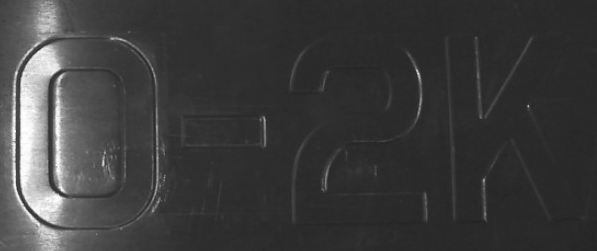

                                                                            （图LBimage3）

**1.设计内容：**

        对给定的图像LBimage3对图像进行滤波，去除光照影响，再进行二值化处理，得到较完整的数字和符号。

**2.设计要求：**

        １）可用ｍａｔｌａｂ或ＶＣ＋＋等语言编程，用ｍａｔｌａｂ编程时，设计中除了读写、显示、

数据类型转换等函数外以外，其它主要功能函数需自己编写。

        ２）所有设计内容要在一个主程序中运行实现，分步骤实现设计要求。

        ３）设计报告中需要分析影响结果的多种因素。

**3.程序：**

3.1 读取并显示原图

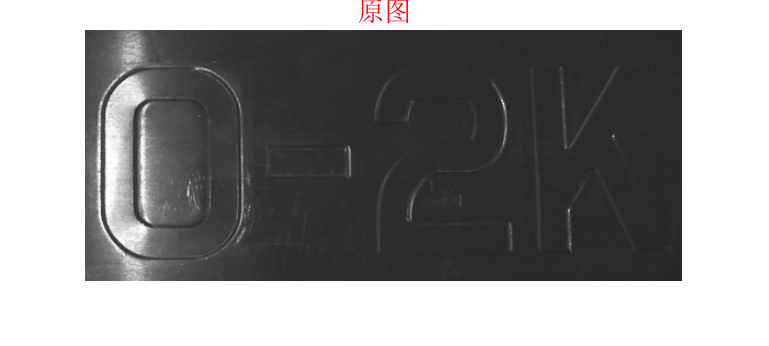

X_src=imread('LBimage3.bmp');
imshow(X_src);title('\fontsize{20}\color{red}原图');

3.2 提取光照部分

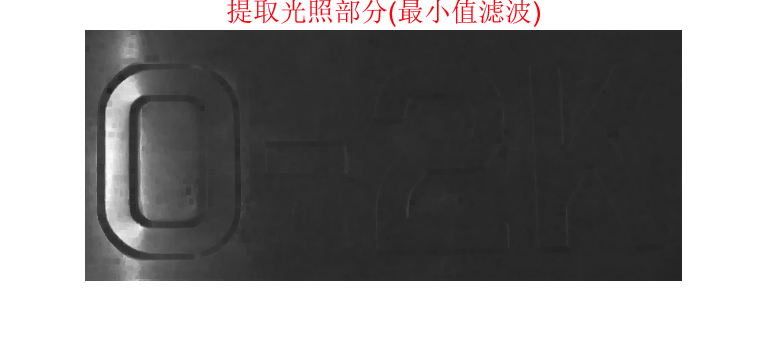

% 最小值滤波
X=double(X_src);     % 计算时需转为double型
X_min1=myfilter2('Minimum',X,5);        
imshow(X_min1);title('\fontsize{20}\color{red}提取光照部分(最小值滤波)');

3.3 抑制噪声

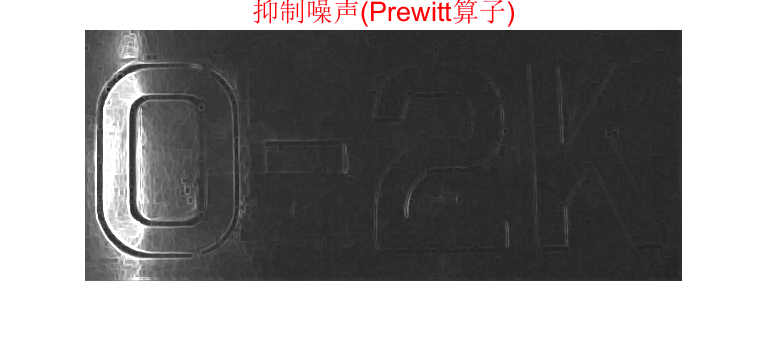

% Prewitt
X_prewitt=myfilter2('Prewitt',X_min1);
imshow(X_prewitt);title('\fontsize{20}\color{red}抑制噪声(Prewitt算子)');

3.4 结果相减（去除光照部分）

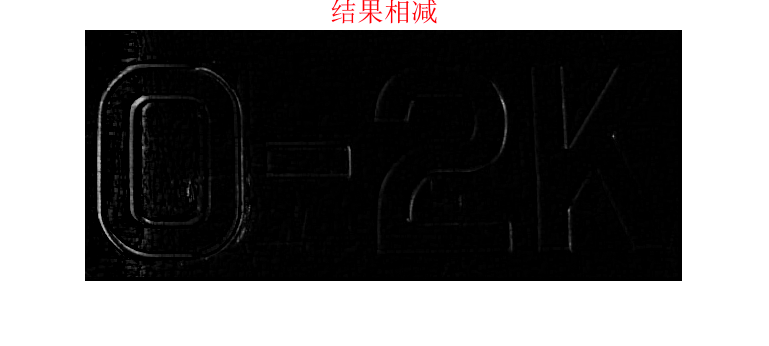

% 无光照图=原图-光照图
X_sub=X_src-uint8(X_prewitt);
imshow(uint8(X_sub));title('\fontsize{20}\color{red}结果相减');

3.5 灰度拉伸

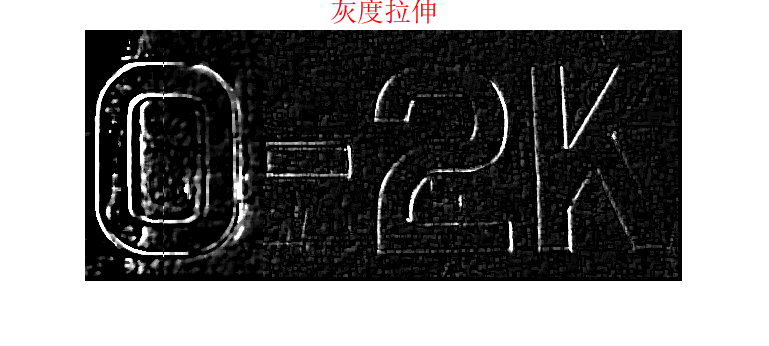

% 对去除光照后的图像进行线性灰度拉伸
NX_sub=13*X_sub;
% 对图像中的数字‘0’进行局部中值滤波
NX_sub(:,1:80)=myfilter2('Medium',NX_sub(:,1:80),5);
NX_sub(:,80:180)=myfilter2('Medium',NX_sub(:,80:180),5);
imshow(uint8(NX_sub));title('\fontsize{20}\color{red}灰度拉伸');

3.6 二值化

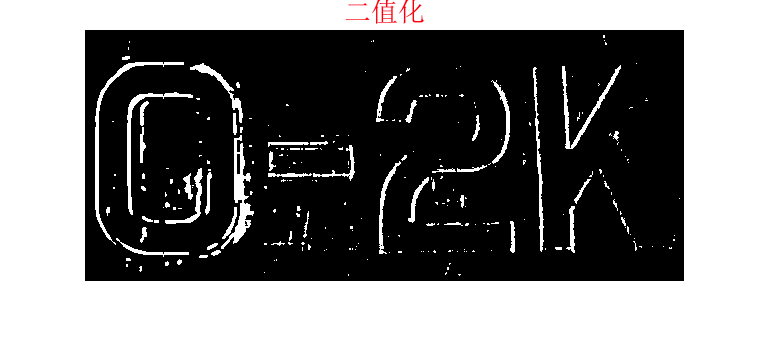

% 对图像进行分段二值化
% 对图像中的数字‘0’分两段进行不同阈值的二值化
left1=myim2bw(NX_sub(:,1:80),0.99);
left2=myim2bw(NX_sub(:,80:180),0.3);
% 合成数字‘0’
BW_left=[left1 left2];
% 对数字‘0’右边进行二值化
BW_right=myim2bw(NX_sub(:,180:size(X,2)),0.3);
% 合成整幅图像
BW=[BW_left BW_right];
imshow(BW);title('\fontsize{20}\color{red}二值化');

% 显示原图，比较处理效果
imshow(X_src);title('\fontsize{20}\color{red}原图');